# IMPORTANT: BEFORE YOU START!

Do **NOT** click on the green run button!

Execute this script by stepping section to section, read instructions and inspect results.

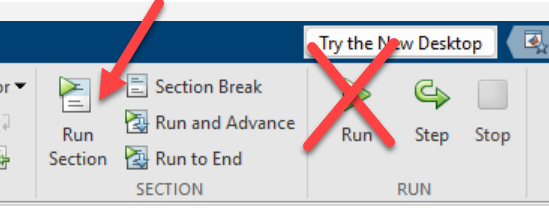

Before you start with the exercises, let's add the folder with the files and solutions required to complete each step.

close all;
clear all;
bdclose all;
clc;

addpath('./Solutions')
addpath('./Files')

# Workshop: Top-Down Design of an RF Receiver and Antenna Front-End Integration

This workshop designs a RF receiver for a 2.4GHz narrowband application using a top-down methodology. It verifies the error rate performance after the addition of impairments such as interfering signals and the integration of the antenna front-end. The example uses the `RF Budget Analyzer` App to rank the elements contributing to the noise and non-linearity budget, and the `Antenna Designer App` to design the antenna.

These are the specifications of the IEEE® 802.15.4 system and the high-level specifications of the receiver:

- Data rate = 250kbps

- OQPSK modulation with half sine pulse shaping

- Direct sequence spread spectrum with chip rate = 2Mchips/s

- Sensitivity specification = -100dBm

- Bit Error Rate (BER) specification = 1e-4

- Analog to digital converter (ADC) with 10 bits and 0dBm saturation power

Based on the above specifications, this [example](https://www.mathworks.com/help/simrf/ug/top-down-design-of-an-rf-receiver.html) shows how to use design heuristics to identify the desired Noise Figure and Gain for the RF receiver:

- **NF = 10.7dB** 

- **G = 51.5dB**

This workshop guides you through the following exercises:

**Exercise 1: **Analyze the RF receiver

- Starting from the receiver Gain and Noise Figure, design and analyze a cascade of RF components

- Analyze the chain with Friis and Harmonic Balance

**Exercise 2: ** Simulate the RF receiver

- Integrate the RF automatically generated model of the RF receiver into the system-level testbench

- Measure the corresponding Chip Error Rate (ChER) in presence of an out-of-band interfering signal

**Exercise 3: ** Integrate a dipole antenna 

- Integrate a simple dipole antenna into the system-level model of the RF receiver

- Understand the impact of polarization mismatch

**Exercise 4: **Integrate a crossed polarized dipole antenna and a Wilkinson combiner

- Design a dual polarized antenna, analyze its performance using EM analysis, and integrate it in the system-level model of the RF receiver

- Design a Wilkinson combiner and integrate it together with the dual polarized antenna into the system-level model

**Exercise 5: **Design a phase shifter and combine it on the PCB with the Wilkinson combiner

- Design a 90-degrees phase shifter and implement it on a PCB together with the Wilkinson combiner

- Analyze the PCB structure using electromagnetic analysis

- Verify the system performance in terms of ChER

## Exercise 1: Analyze the RF receiver

Number of steps: 3 

Expected completion time: 20 minutes

In this section, the RF receiver with the desired noise figure and gain specifications is implemented and analyzed with the RF Budget Analyzer app.

**1.1 **Launch at the command line the RF Budget Analyzer app and construct a chain of elements with the characteristics shown below:

rfBudgetAnalyzer

Specify the following system parameters representing the **desired input signal **to the receiver:

- input frequency = 2.45GHz                

- available input power = -100dBm

- bandwidth = 4MHz

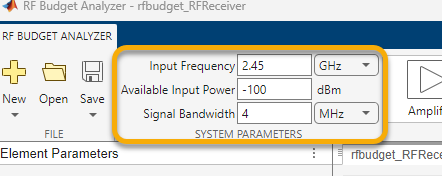

From the elements gallery, add the following components to the chain:

- S-parameters SAW filter described by means of the Touchstone file *SAWfilter.s2p*

- Amplifier (LNA) with Gain = 22dB,  Noise Figure = 7dB, OIP3 = 30dBm

- Demodulator with Local Oscillator = 2.45GHz,  Gain = -7dB, OIP2 = 55dBm, Noise Figure = 10dB

- Amplifier (VGA) with Gain = 40dB, Noise Figure = 14dB, OIP3 = 35dBm

The chain should look like this, with a total transducer gain of ~52dB, and noise figure of 10.5dB.

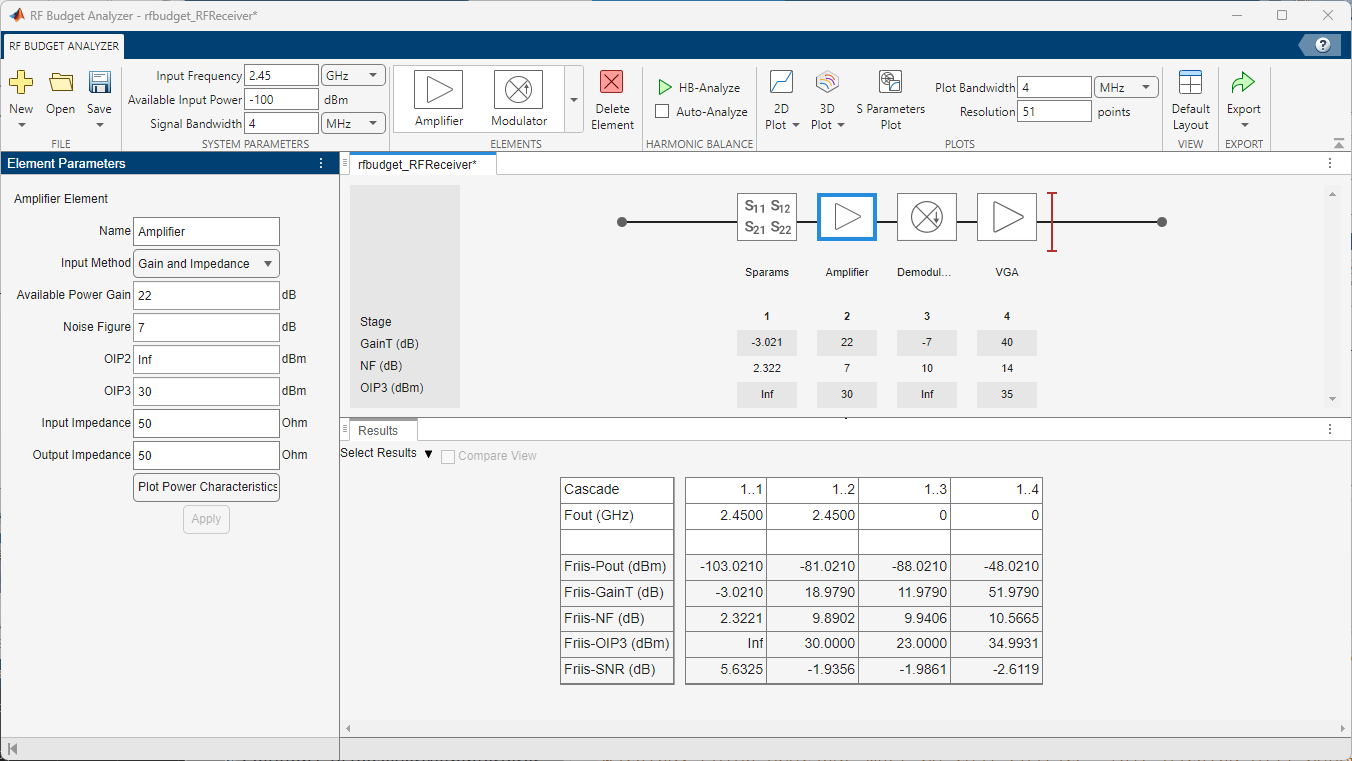

**1.2 **Compare budget results obtained with Friis equations and **Harmonic Balance** (HB) analysis and verify the noise, gain, SNR budget of the RF chain for the incoming signal.

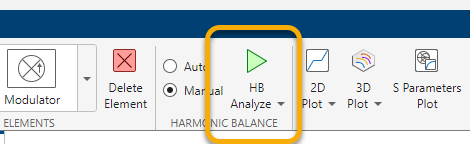

Suggestion: click on compare view in the results table.

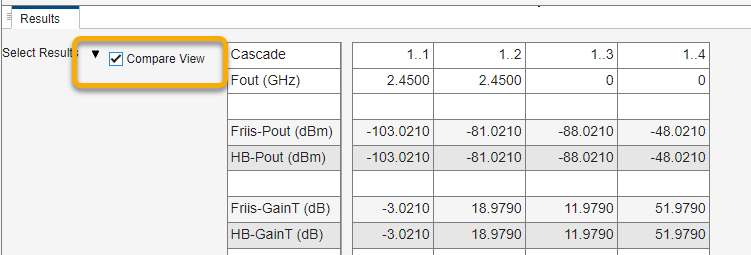

Results computed with Friis equations assume mild non-linear conditions. Harmonic Balance provides an accurate non-linear analysis of the chain based on the power of the input signal. As the power of the input signal does not excite any non-linearity, results provided by Friis and Harmonic Balance are identical.

**1.3 ** Change the system parameters to represent an **out of band interfering signal:**

- center frequency = 2.5GHz                

- available input power = -30dBm

- bandwidth = 4MHz

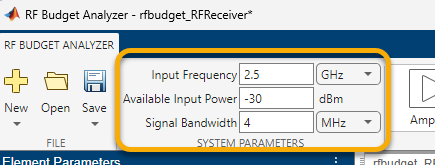

Compare budget results obtained with Friis equations and Harmonic Balance analysis and verify the noise, gain, SNR budget of the RF chain. 

*Why is the transducer gain predicted by HB 0.5dB lower than the transducer gain predicted by Friis? *

*What can you say about the impact of the interfering signal on the RF receiver operating mode and output power?*

Suggestions:

- click on compare view in the results table

- visualize power characteristics for the two amplifiers

**Solution **

Execute the command below to visualize the RF receiver chain in the **RF Budget Analyzer** app.

rfBudgetAnalyzer('rfbudget_RFReceiver.mat') 

The interfering signal has higher power than the desired signal, and it is entering the saturation region of the VGA. Although the interfering signal is centered around a different frequency, saturation effects will impact also the desired signal and will ultimately result into higher ChER.

This can be visualized by plotting the power characteristic of the VGA amplifier either in the budget app or in the block mask.

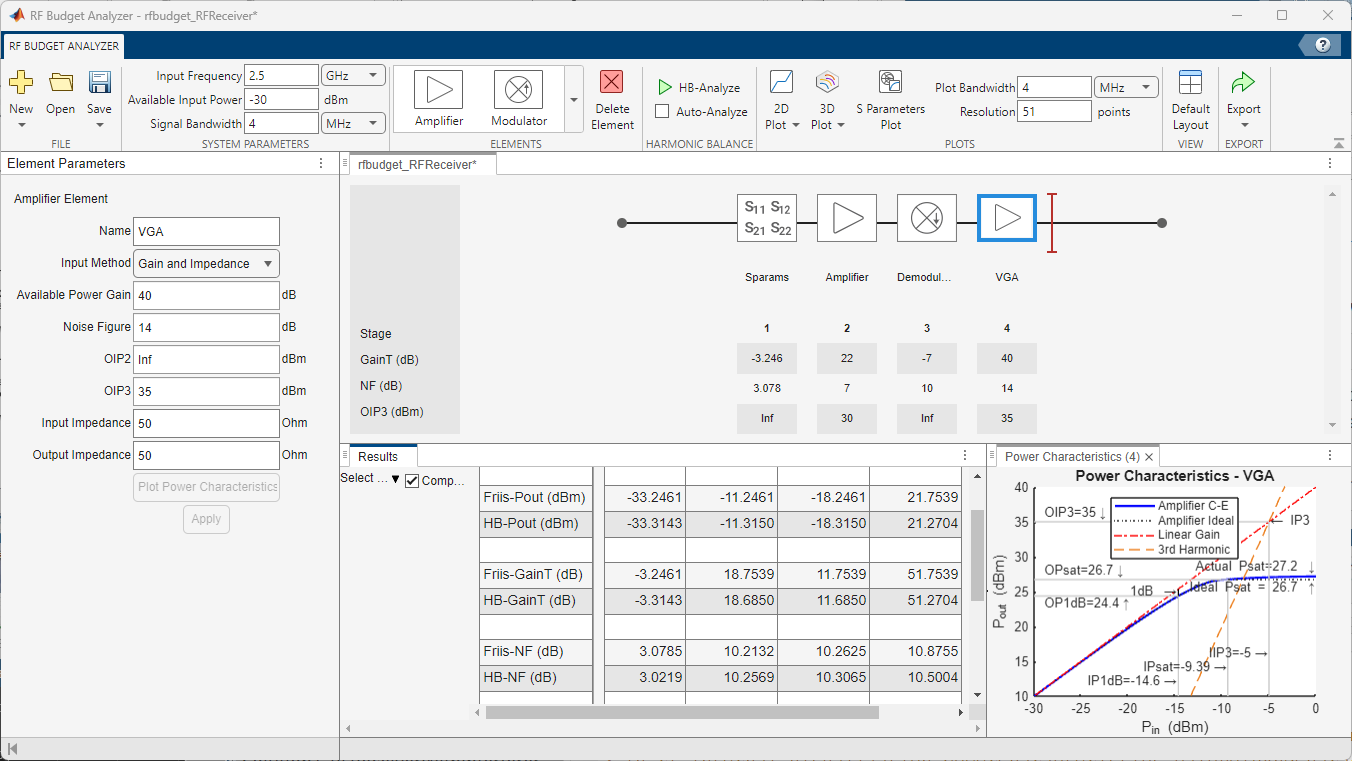

**Exercise outcome and summary**

In this first exercise, you learned how to analyze the RF budget of a receiver starting from high-level specifications and verify results using two different techniques: Friis and Harmonic Balance.